# Task 1

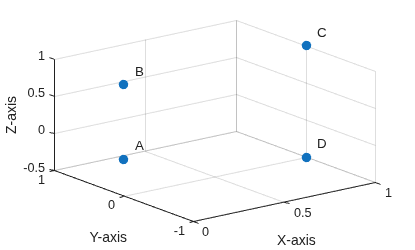

A= [0 0 0 0 0 0];
B=[0 0 1 0 pi/2 0];
C=[1 0 1 0 -pi 0];
D=[1 0 -0.5 0 pi/2 0];
x=[A(1) B(1) C(1) D(1)];
y=[A(2) B(2) C(2) D(2)];
z=[A(3) B(3) C(3) D(3)];
function plot_points(x,y,z)
    labels = {'A', 'B', 'C', 'D'};
    scatter3(x, y, z, 50, 'filled');
    hold on;
    dx = 0.1; dy = 0.1; dz = 0.1;
    text(x + dx, y + dy, z + dz, labels);
    grid on;
    xlabel('X-axis');
    ylabel('Y-axis');
    zlabel('Z-axis');
end

plot_points(x,y,z)
hold off;

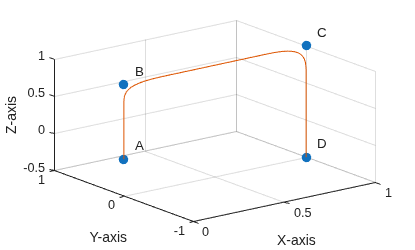

via = [B(1:3); C(1:3); D(1:3)];
tseg = [1 1 1];
q0 = A(1:3);

% Sampling time
dt = 0.01;

% Acceleration time
tacc = 0.5;

% Generate trajectory
q = mstraj(via, [], tseg, q0, dt, tacc);

% Generate time vector
t = (0:size(q,1)-1)*dt;
plot_points(x,y,z)
plot3(q(:,1), q(:,2), q(:,3))
hold off;

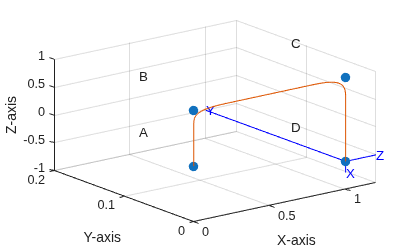

via = [B(4:6); C(4:6); D(4:6)];
q0 = A(4:6);
rpy = mstraj(via, [], tseg, q0, dt, tacc);

plot_points(x,y,z)
plot3(q(:,1), q(:,2), q(:,3))
T = SE3(q) .* SE3.rpy(rpy);
T.animate('length', 0.2);
%T.animate('movie', 'trajectory.gif', 'length', 0.2);
hold off